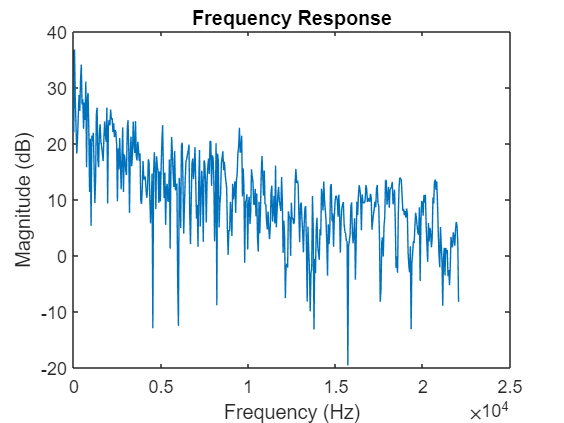

clc, clear all;

input = 'u2_ilmapallo_02-Nov-2023_12_47_13_465.wav';

% Read the input file
[y, Fs] = audioread(fullfile('nauhoitukset', input));

% Convert to mono if the audio is stereo
if size(y, 2) == 2
    y = sum(y, 2) / 2;
end

% Impulse response and frequency response analysis
impulse_response = y;
[h, t] = impz(impulse_response);
freq_response = freqz(h);

% Plot frequency response
figure;
plot(linspace(0, Fs/2, length(freq_response)), 20*log10(abs(freq_response)));
title('Frequency Response');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');

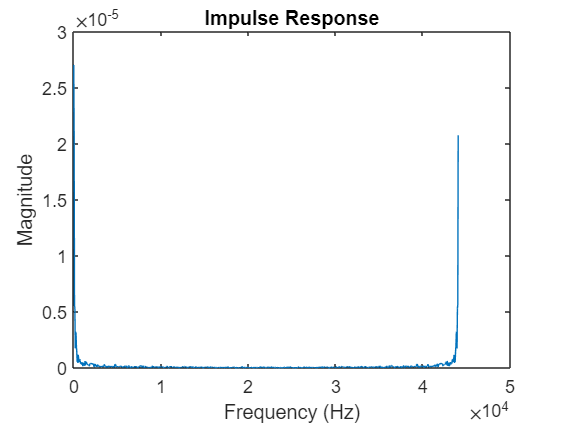


% Plot the impulse response
% Window and FFT for the first audio file
y_windowed = y .* hann(length(y));
Y = fft(y_windowed, 1024);
f = (0:length(Y)-1) * Fs / length(Y);

figure;
plot(f, abs(Y));
title('Impulse Response');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

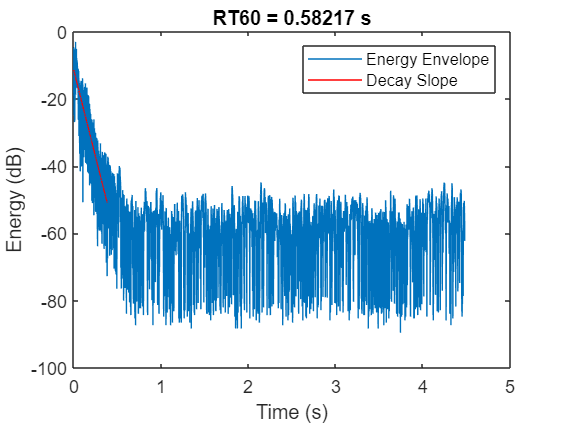


% Calculate reverbation time
RT60 = reverbation_time(input);


% Categorize room type
roomType = categorizeRoomType(RT60);

fprintf(['Based on the reverbation time = ', num2str(round(RT60,2)), ' s, the room type is: ', roomType])

Based on the reverbation time = 0.58 s, the room type is: Indoors